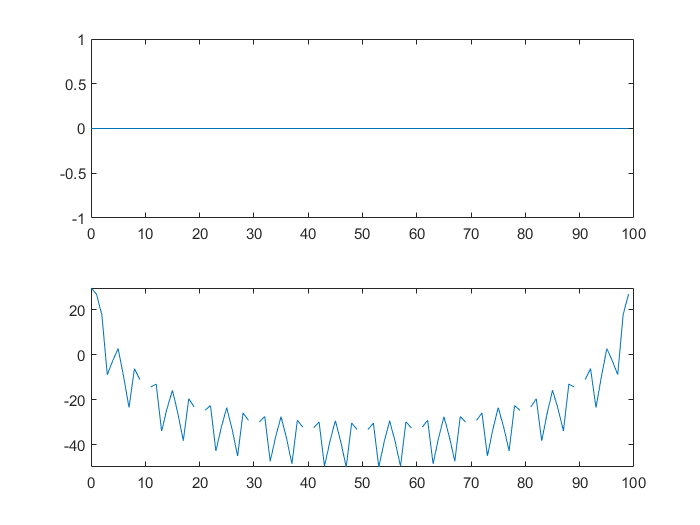

clear all;
close all;
clc;

% DFT for the impulse. 
impulse = zeros(1, 100);
impulse(1) = 1; % Assume the range of x is 0 to 99.  
impulse_fft = fft(impulse);
impulse_fft_mag = abs(impulse_fft);
k = 0:99;
subplot(2,1,1);
plot(k, mag2db(impulse_fft_mag));
% DFT for the triangle.
% Triangle signal
x = 0:99;
triangle = (30 - abs(x-30)) / 30;
triangle(61:100) = 0;
triangle_fft = fft(triangle);
triangle_fft_mag = mag2db(abs(triangle_fft));
subplot(2,1,2);
plot(k, triangle_fft_mag);

conjucate_temp =    1.0000 +30.0000i -20.0302 - 6.8331i   5.4949 - 6.1867i   1.2113 + 0.2908i   0.3027 + 0.2266i   1.0000 - 1.3621i   1.3119 + 0.1014i   0.9607 + 0.0541i   0.7135 - 0.3944i   1.2666 - 0.0866i   1.0000 - 0.0000i   0.8192 - 0.0588i   1.1308 - 0.1800i   1.0119 + 0.0163i   0.9396 + 0.0196i   1.0000 - 0.1617i   1.0472 + 0.0153i   0.9928 + 0.0099i   0.9383 - 0.0850i   1.0657 - 0.0213i   1.0000 + 0.0000i   0.9448 - 0.0179i   1.0436 - 0.0600i   1.0043 + 0.0059i   0.9766 + 0.0076i   1.0000 - 0.0667i   1.0206 + 0.0067i   0.9967 + 0.0046i   0.9701 - 0.0411i   1.0332 - 0.0108i   1.0000 + 0.0000i   0.9697 - 0.0099i   1.0249 - 0.0342i   1.0025 + 0.0035i   0.9857 + 0.0046i   1.0000 - 0.0420i   1.0134 + 0.0043i   0.9978 + 0.0031i   0.9795 - 0.0282i   1.0234 - 0.0076i   1.0000 + 0.0000i   0.9775 - 0.0073i   1.0189 - 0.0260i   1.0020 + 0.0027i   0.9886 + 0.0037i   1.0000 - 0.0342i   1.0111 + 0.0036i   0.9981 + 0.0026i   0.9822 - 0.0245i   1.0208 - 0.0067i


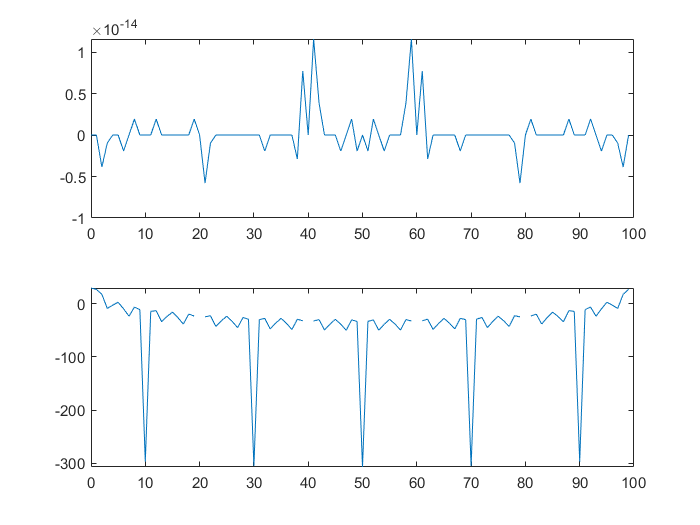

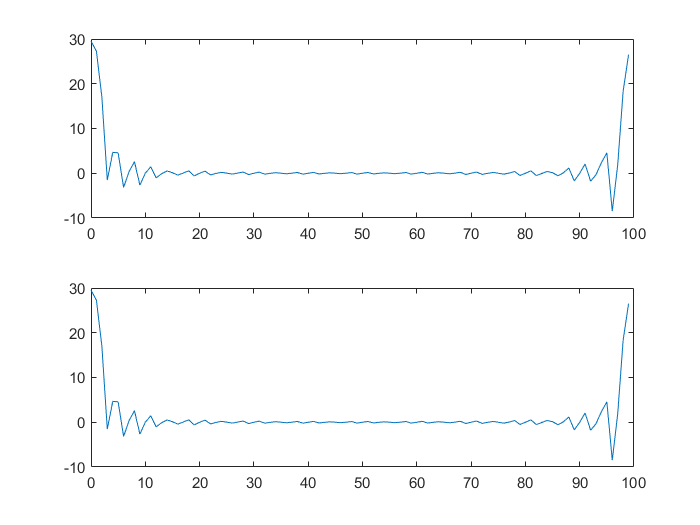


dualIFFT(impulse, triangle);

function dualIFFT(x, y)
v = x + j*y;
fft_for_v = fft(v);
conjucate_temp = [fft_for_v(1), fft_for_v(end:-1:2)];
fft_for_x = (fft_for_v + conj(conjucate_temp)) / 2;
fft_for_y = (fft_for_v - conj(conjucate_temp)) / (2*j);
k = 0:99;
figure
subplot(2,1,1);
plot(k, mag2db(abs(fft_for_x)));
subplot(2,1,2);
plot(k, mag2db(abs(fft_for_y)));
figure
subplot(2,1,1);
plot(k, mag2db(abs(fft_for_v)));
subplot(2,1,2);
Vk_by_two_parts = fft_for_x + j*fft_for_y;
plot(k, mag2db(abs(Vk_by_two_parts)));
end